# SMF Online application example

Author: Lea Bouffaut, PhD 

Naval Academy Research Institute, Brest, France.

Date: 10-30-2019

Full description of the method's theory is given in 

L. Bouffaut, R. Dreo, V. Labat, A. Boudraa and G. Barruol, 'Passive stochastic matched filter for antarctic blue whale call detection,' in J. Acoust. Soc. Am, 144(2) (2018).

and any use of this material should refer accordingly.

Before to be able to run the online application of the SMF: 

- (1) run 'Offline_save_Z-call.m' to simulate the signal and estimate its covariance matrix, 

- (2) run 'Offline_save_filterbank.m' to design the filter bank that maximizes the output SNR. 

For easy use, required matrices are already saved in the "Offline_saved" folder. An example observation recording containing high SNR Z-calls is added to the 'SMF_package' folder.

## Load signal 

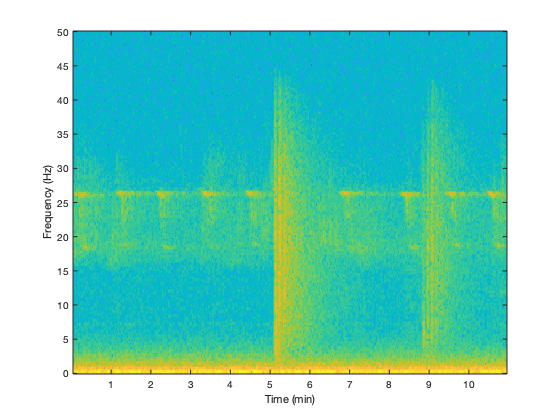

clearvars    %MATLAB2016
close all
clc

addpath Functions
addpath Offline_saved

% Spectrogram parameters
fft_size = 512;
overlap = 98; % \% de recouvrement

% Load file
name = 'RR44_2013_D151.wav';
padding =  1; %(min)
duree =  10 + padding; %(min)
heure = 12.34;

[x, fs] = cutfile_generalized(name, heure, duree);
Tx = (length(x)-1)/fs; % Signal duration (s)
tx = 0:1/fs:Tx; % temporal axis (s)
M = length(x);

% Spectrogram
[stft,f,t,p] = spectrogram(x/max(x),hann(fft_size),round((overlap/100)*fft_size),fft_size,fs);
p = 10*log10(p);
    
figure
imagesc(t/60,f,p)
axis xy; axis tight; %colormap gray 
xlabel('Time (min)');
ylabel('Frequency (Hz)');
set(gca,'clim',[-155 2])

## Online application of the Stochastic Matched Filter

### Loading signal covariance, noise and SNR estimation

% Load signal covariance matrix and eigenvectors
load s_whale.mat ;
N = length(covs);

% Definition of the size of the median filter for background noise
% estimation AND SNR estimation
% The median filter size =~ duration of the Z-cal in the TF representation
med_win_size = 201; 

% Observation noise estimation preprocessing + SNR estimation
[covn, Qmax,snr] = SMF_noise_rsb_preprocess_median_phase(x,fs,fft_size,overlap,N,med_win_size);


### Generalized Eigenvalue Problem

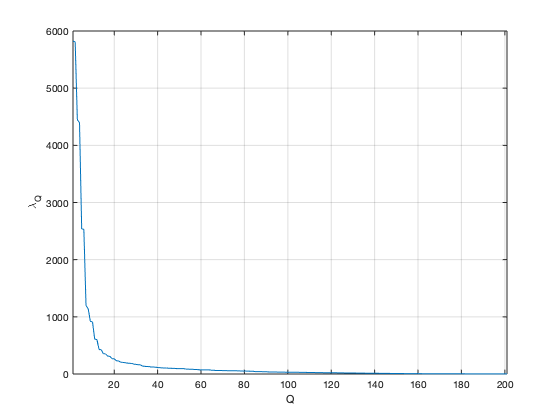

% For Lambda estimation
load('filtre_lambda.mat')

% Limit the max number of filter, Qmax
[~,b] = size(h);
if b < Qmax, Qmax = b; end ; clear a b

% Estimation of the observation's eigenvalues
Lambda_zcall = SMF_GEP_lambda(vecs, covs, covn, Qmax);

figure
plot(1:Qmax,Lambda_zcall)
xlabel('Q'); ylabel('\lambda_Q')
xlim([1 Qmax])
grid on

### "Real time" application 

% This is realized using a sliding window to insure stationarity
% Empty matrix declaration
s = zeros(1,M);
Q = zeros(1,M); % <=> Q !!
z_0  = zeros(1,M+N-1);

% if even or odd
if mod(N,2)==0
    z_0(N/2:end-N/2) = x;
else
    z_0((N+1)/2:end-(N-1)/2) = x;
end

% Application of the SMF filters
for n=1:M
    % Window the observation (we're looking at the center sample)
    zm = z_0(n:n+N-1);

    % Estimation of the number of filters Q to apply to the center sample (n)
    % Q = number of (eigenvalues * snr) > 1 at the discreet time n 
    Q(n) = sum((abs(Lambda_zcall)*snr(n))>1); 
    % If none are >1, we only take the first filter
    if Q(n)<=0, Q(n)=1; end % Q must be >=1
    
    % Application of the filter to the observation
    s(n) = zm*h(:,Q(n)); % Reconstruction du signal
    clear zm
end


## MF compared to the SMF + MF

### Application

% reference signal zero-padding
s_0padded = zeros(1,length(x));
s_0padded(1:N) = s_whale ;

% MF on band-pass filtered observation
[b,a]=butter(20,15/(fs/2),'high'); x_filt = filter(b,a,x); % Filtrage des frequences en dessous de 15 Hz 
[b,a]=butter(30,30/(fs/2),'low'); x_filt = filter(b,a,x_filt); % Filtrage des frequences au dessus de 30 Hz 

CORR_MF_interm = xcorr(x_filt,s_0padded,'coef');
CORR_MF_interm = CORR_MF_interm(M-floor(N/2):end-floor(N/2));
CORR_MF = zeros(1,M);

% SMF + MF
CORR_SMF = zeros(1,M);
CORR_SMF_interm = xcorr(s,s_0padded,'coef');
CORR_SMF_interm = CORR_SMF_interm(M-floor(N/2):end-floor(N/2));

% Correlation max
win_size = 200;
for j = 1 :M - win_size
     CORR_MF(j+floor(win_size/2)) = max( CORR_MF_interm(j:j+win_size));
    CORR_SMF(j+floor(win_size/2)) = max(CORR_SMF_interm(j:j+win_size));
end


### Remove the 1 minute padding

% Spectrogram
debspc = find(t/60>= padding/2,1);
finspc = find(t/60>=duree-padding/2,1);
p = p(:,debspc:finspc);
t = linspace(0,duree,length(p));

% On time vectors
deb = find(tx/60>= padding/2,1);
fin = find(tx/60>=duree-padding/2,1);

Tx_new = Tx - padding*60;
tx_new = (0:1/fs:Tx_new-1/fs)/60;
M = length(tx_new);
s = s(deb:fin);
x = x(deb:fin);
x_filt = x_filt(deb:fin);
snr = snr(deb:fin);
Q = Q(deb:fin);
CORR_SMF = CORR_SMF(deb:fin);
CORR_MF = CORR_MF(deb:fin);

## Plot

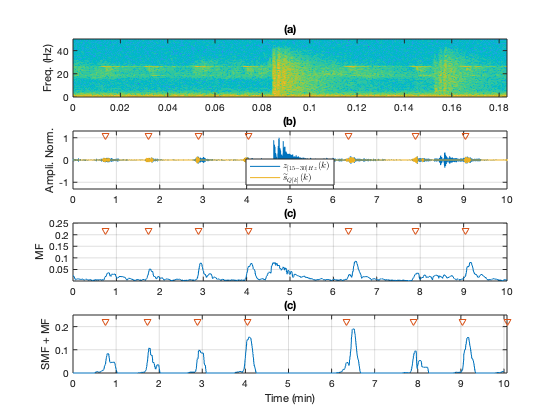

% Hand annotation of the calls 
pres_zcall_time = [0.57 1.55 2.72 3.87 6.17 7.71 8.86 9.89];
% pres_zcall_time = [-0.1 1 2 3.15 4.26 6.6 8.2 9.31]+0.1; % RR43
corr_shift = 0.22;
pres_zcall_time = pres_zcall_time+0.18;


fontsize = 10;

fig = figure;
subplot(4,1,1);
imagesc(t/60,f,p);
axis xy; axis tight; %colormap gray 
%xlabel('Time (min)');
%ylim([2 50])
ylabel('Freq. (Hz)');
title('(a)') % SPECTROGRAMME
set(gca, 'fontsize', fontsize);

subplot(4,1,2)
plot(tx_new,x_filt/max(x_filt))
hold on
plot(tx_new,(s/max(x_filt)),'Color',[0.9290 0.6940 0.1250])
plot(pres_zcall_time,1.1*ones(size(pres_zcall_time)),'v','Color',[0.8500 0.3250 0.0980]) % marqueurs
grid on
%xlabel('Time (min)')
ylabel('Ampli. Norm.')
leg1 = legend(' $z_{[15 - 30]Hz}(k)$ ','$\widetilde{s}_{Q[k]}(k)$','Location','South');
set(leg1,'Interpreter','latex');
xlim([0 Tx_new/60])
ylim([-1.3 1.3])
title('(b)') % IN/OUT
set(gca, 'fontsize', fontsize);
box on

subplot(4,1,3)
title('(c)') % MF Classique
hold on 
% plot(tx_new,(CORR_MF_interm))
plot(tx_new,(CORR_MF))
plot(pres_zcall_time,corr_shift*ones(size(pres_zcall_time)),'v','Color',[0.8500 0.3250 0.0980]) % marqueurs
xlim([0 Tx_new/60]) ; grid on
%ylim([0 0.002])
%xlabel('Time (min)')
ylabel('MF')
set(gca, 'fontsize', fontsize);
ylim([0 0.25])
box on

subplot(4,1,4)
title('(c)') % CORR_SMF 
hold on
% plot(tx_new, CORR_SMF_interm)
plot(tx_new, CORR_SMF)
plot(pres_zcall_time,0.22*ones(size(pres_zcall_time)),'v','Color',[0.8500 0.3250 0.0980]) %marqueurs
xlim([0 Tx_new/60]) ; grid on
%ylim([0 0.2])
xlabel('Time (min)')
ylabel('SMF + MF')
hold on
ylim([0 0.25])
set(gca, 'fontsize', fontsize);
box on

subplot(4,1,2)
xlim([0.00 10.00])
ylim([-1.3 1.3])
legend({'$z_{[15 - 30]Hz}(k)$','$\widetilde{s}_{Q[k]}(k)$'},'Location','south')


% Nom = ['/Users/Lea/Documents/03. REDACTION/00_PhD_Thesis/Chapter3/PICTURES/' name ];
% tightfig;
% orient(fig,'portrait')
% saveas(gcf,Nom,'pdf')